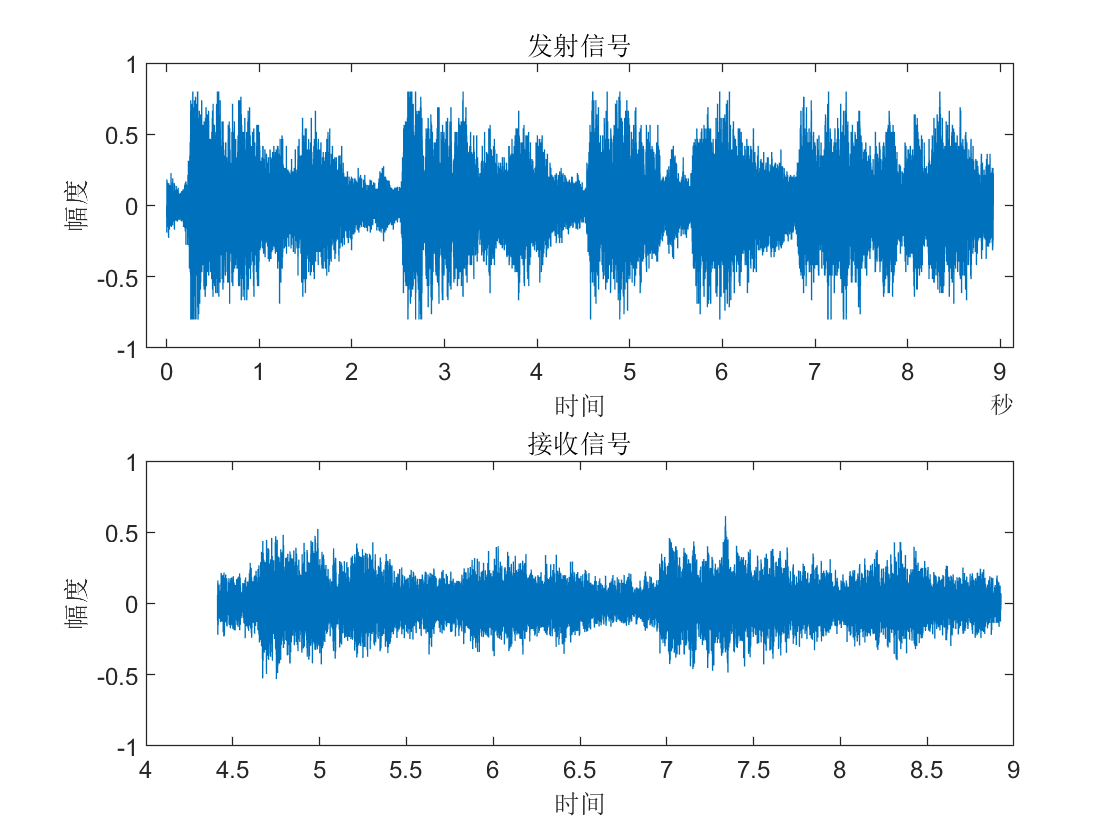

clear;
[y,Fs] = audioread('handel.wav');%读取音乐

info = audioinfo('handel.wav');%获取音乐信息
t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);
distance1=500;%第一个障碍物多出的距离为5KM
distance2=1500;%第二个障碍物多出的距离为20KM
v_sound=340;%声音的传播速度340m/s
alpha1=0.2;%第一条信道衰减系数
alpha2=0.3;%第二条信道衰减系数
alpha3=0.5;%第三条信道衰减系数

subplot(2,1,1);
plot(t,y);
title('发射信号');
xlabel('时间');
ylabel('幅度');
% y1=fft(y);%y1为频谱曲线
% y1=fftshift(y1);%快速傅里叶变换
% subplot(312);
% plot(abs(y1));
x = 1:1:73113;
y2=y(x);        %y2为接收信号

% for temp=1:73113
%     if temp<distance1/v_sound
%        f=alpha1*y2(temp); 
%     end

temp=int64(Fs*distance2/v_sound);
x=temp+1:1:73113;
f=alpha1*y2(x)+alpha2*y2(x-int64(distance1/v_sound*Fs))+alpha3*y2(x-int64(distance2/v_sound*Fs));%响应表达式

subplot(2,1,2);
x=double(x);
plot(x/Fs,f);
xlim([4.00, 9.00]);
ylim([-1 ,1]);
title('接收信号');
xlabel('时间');
ylabel('幅度');

sound(y,Fs);%播放原始音乐
pause(9);%等待9秒使音乐放完

sound(f,Fs);%播放变换过音乐

